## Udregning af akustisk frekvenskarakteristik

clear all

**Model for lukket kabinet:**

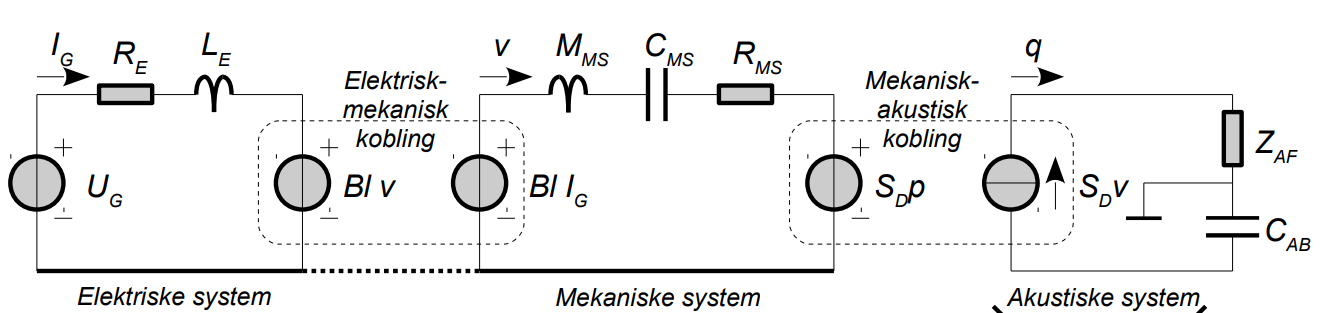

**Model for bass-reflex**

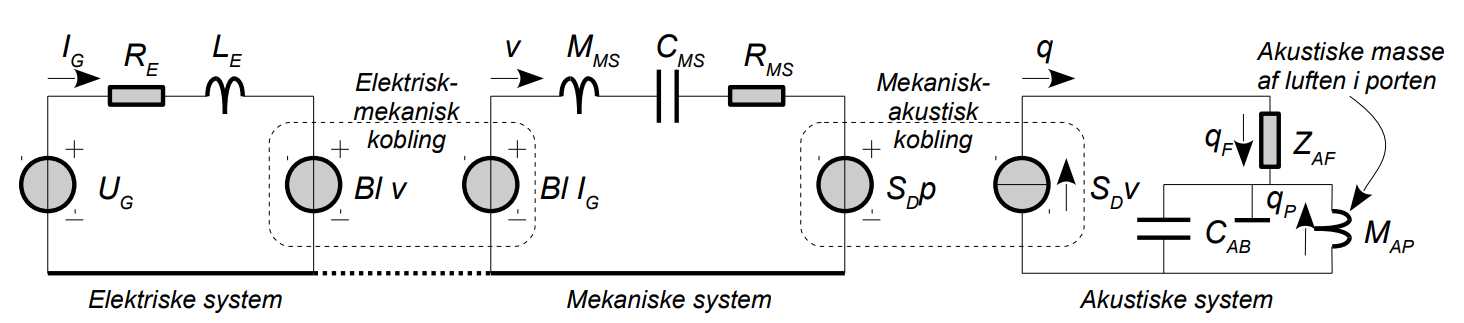

**Ækvivalent load (lukket forside - 4th order):**

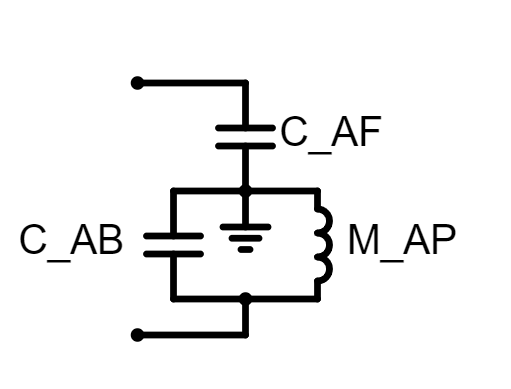

#### Ækvivalent load (ported forside - 6th order)

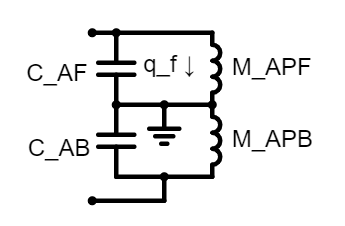

#### Højtalerparametre:

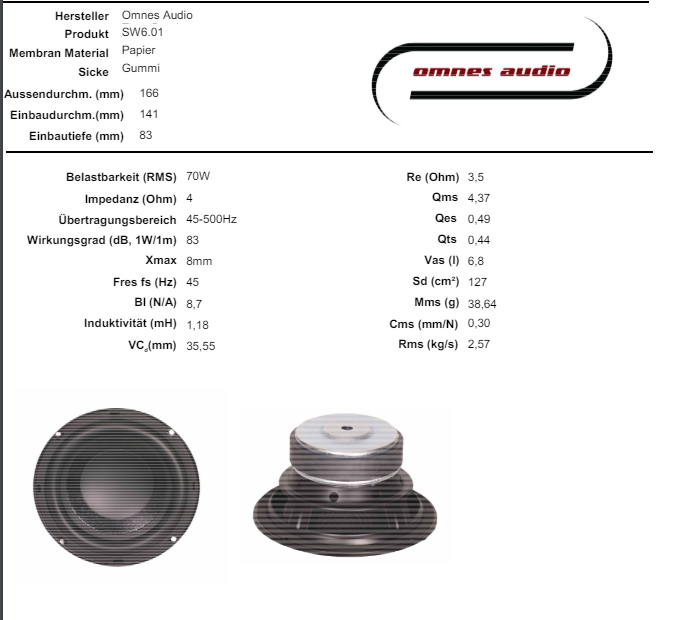

#### Elektrisk:

ts.Re = 3.5; % Ohm
ts.Le = 1.18e-3; % H
ts.Bl = 8.7; % N/A

#### Mekanisk:

ts.Mms = 38.64e-3; % kg
ts.Cms = 0.3e-3; % m/N
ts.Rms = 2.57; % kg/s
ts.Sd = 127e-4 % 127cm^2 in m^2

ts = struct with fields:
     Re: 3.5000
     Le: 0.0012
     Bl: 8.7000
    Mms: 0.0386
    Cms: 3.0000e-04
    Rms: 2.5700
     Sd: 0.0127


#### Akustisk:

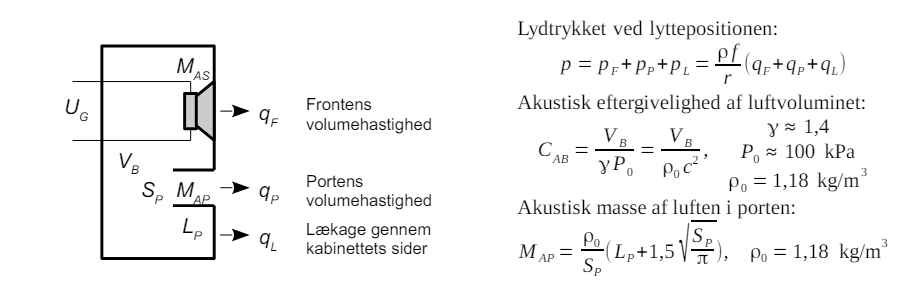

% find en passende strålingsimpedans
syms s
c = 343; % m/s
rho0 = 1.18; % kg/m^3


$$\begin{array}{l}
k=\frac{2\;\pi }{\lambda }\\
\lambda =\frac{c}{f}=\frac{c}{\left(\frac{\omega }{2\pi }\right)}=\frac{2\pi c}{\omega }\\
k=\frac{2\;\pi }{\left(\frac{2\pi c}{\omega }\right)}=\frac{2\pi \omega }{2\pi c}=\frac{\omega }{c}=\frac{s}{j\;c}
\end{array}$$


 % Bassreflex
back_box_volume = (8e-1)^3 / 1000; % liters (cubic decimeters) in m^3
back_port_len = 84e-3; % 84 mm
back_port_diameter = 15e-3 * 2; % 15 mm radius
back_port_s_p = pi*(back_port_diameter/2)^2;
back_C_AB = back_box_volume/(rho0*c^2)

back_C_AB = 3.6881e-09

back_M_AP = rho0/back_port_s_p * (back_port_len+1.5*sqrt(back_port_s_p/pi))

back_M_AP = 177.7867

Z_C_AB = 1/(back_C_AB*s);
Z_M_AP = s*back_M_AP;
Zaf_val = 0;
Zab_val = (Z_C_AB * Z_M_AP)/(Z_C_AB + Z_M_AP);

Strøm i spole (strømdelerformel)


$$\begin{array}{l}
S_D \;v=-q_{C_{\mathrm{AB}} } -q_P \\
q_P =\frac{\frac{1}{s\;C_{\mathrm{AB}} }}{\frac{1}{s\;C_{\mathrm{AB}} }+s\;M_{\mathrm{AP}} }\;S_D \;v\\
H_{\mathrm{qP}} =\frac{q_P }{S_D \;v}=\frac{\frac{1}{s\;C_{\mathrm{AB}} }}{\frac{1}{s\;C_{\mathrm{AB}} }+s\;M_{\mathrm{AP}} }
\end{array}$$


H_qP = Z_C_AB/(Z_C_AB + Z_M_AP);

#### Overføringsfunktion elektrisk:

Der regnes fra højre i diagrammet mod venstre for at afkoble kredsløbene (kredsløbet ses fra den elektriske sidde).

Superposition mellem kilderne bruges i hver "loop" for at finde "strøm"-bidrag.

"Solve" bruges da udtrykkene bliver meget lange og da eksempeltvis $v$ og $I_G$ kommer til at stå på begge sider af lighedstegnet.

syms I_G U_G Bl Re s Le Sd p Mms Cms Rms v Zab Zaf
p = Sd*v*Zab + (-Sd*v)*Zaf;
v = simplify(solve(v == (Bl*I_G)/(s*Mms + 1/(s*Cms) + Rms) - (Sd * p)/(s*Mms + 1/(s*Cms) + Rms), v));
I_G = simplify(solve(I_G == U_G/(Re + s*Le) - (Bl*v)/(Re + s*Le), I_G))

$$I\_G = \frac{U_{G}}{\left(\frac{{\mathrm{Bl}}^{2}\,\mathrm{Cms}\,s}{\left(\Re+\mathrm{Le}\,s\right)\,\left(\mathrm{Cms}\,\mathrm{Rms}\,s+\mathrm{Cms}\,\mathrm{Mms}\,s^{2}+\mathrm{Cms}\,{\mathrm{Sd}}^{2}\,\mathrm{Zab}\,s-\mathrm{Cms}\,{\mathrm{Sd}}^{2}\,\mathrm{Zaf}\,s+1\right)}+1\right)\,\left(\Re+\mathrm{Le}\,s\right)}$$

Læg mærke til $p$ og $v$ nu er koblet af udtrykket for $I_G$. Nu kan $H_Z \left(s\right)=\frac{U_G \left(s\right)}{I_G \left(s\right)}$ findes.

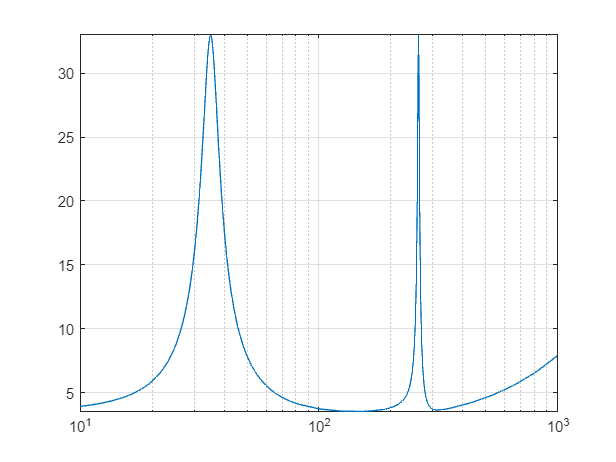

H_Z(s) = simplify(U_G/I_G);
H_Z(s) = simplify(subs(H_Z(s), [Re, Le, Bl, Mms, Cms, Rms, Sd, Zaf, Zab], [ts.Re, ts.Le, ts.Bl, ts.Mms, ts.Cms, ts.Rms, ts.Sd, Zaf_val, Zab_val]));
figure(2)
syms omega
plt = fplot(abs(H_Z(2*pi*1j*omega)));
g = gca;
g.XScale = "log";
g.YScale ="linear";
xlim([1e1, 1e3])
grid on

#### Overføringsfunktion Akustisk:

Der regnes fra venstre i diagrammet mod højre for at afkoble kredsløbene (kredsløbet ses fra den akustiske side).

Fremgangsmåden er den samme som for overførselsfunktion for den elektriske impedans.

syms I_G U_G Bl Re s Le Sd p Mms Cms Rms v Zab Zaf
I_G = simplify(solve(I_G == U_G/(Re + s*Le) - (Bl*v)/(Re + s*Le), I_G));
v = simplify(solve(v == (Bl*I_G)/(s*Mms + 1/(s*Cms) + Rms) - (Sd * p)/(s*Mms + 1/(s*Cms) + Rms), v));

press_conv_fact = rho0*s/(2*pi*1);

p_f = simplify(solve(p == Sd*v*press_conv_fact, p));
p_b = simplify(solve(p == -Sd*v*H_qP*press_conv_fact, p));
p_tot = simplify(solve(p == (Sd*v - Sd*v*H_qP)*press_conv_fact, p));

Læg mærke til $I_G$ og $v$ nu er koblet af udtrykket for $p$. Nu kan $H_p \left(s\right)=\frac{p\left(s\right)}{U_G \left(s\right)}$ findes.

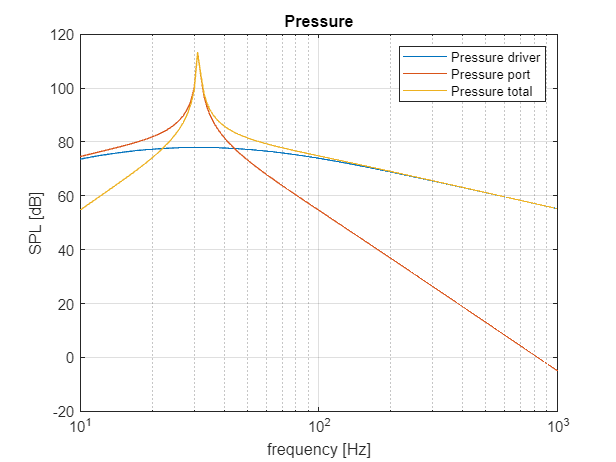

H_Pf(s) = simplify(p_f/U_G);
H_Pf(s) = simplify(subs(H_Pf(s), [Re, Le, Bl, Mms, Cms, Rms, Sd, Zaf, Zab], [ts.Re, ts.Le, ts.Bl, ts.Mms, ts.Cms, ts.Rms, ts.Sd, Zaf_val, Zab_val]));
H_Pb(s) = simplify(p_b/U_G);
H_Pb(s) = simplify(subs(H_Pb(s), [Re, Le, Bl, Mms, Cms, Rms, Sd, Zaf, Zab], [ts.Re, ts.Le, ts.Bl, ts.Mms, ts.Cms, ts.Rms, ts.Sd, Zaf_val, Zab_val]));
H_Ptot(s) = simplify(p_tot/U_G);
H_Ptot(s) = simplify(subs(H_Ptot(s), [Re, Le, Bl, Mms, Cms, Rms, Sd, Zaf, Zab], [ts.Re, ts.Le, ts.Bl, ts.Mms, ts.Cms, ts.Rms, ts.Sd, Zaf_val, Zab_val]));
P_ref = 20e-6;
figure(2)
f = 1e1:1e3;
omega = 2*pi*f;
plt = plot(f, 20*log10(abs(H_Pf(2*pi*1j*omega))/P_ref));
hold on
plot(f, 20*log10(abs(H_Pb(2*pi*1j*omega))/P_ref));
plot(f, 20*log10(abs(H_Ptot(2*pi*1j*omega))/P_ref));
hold off
legend(["Pressure driver", "Pressure port", "Pressure total"])
g = gca;
g.XScale = "log";
xlim tight
grid on
title("Pressure")
xlabel("frequency [Hz]")
ylabel("SPL [dB]")